# FUELSTEPWISE

Fit and evaluate linear models of fuel economy using stepwise fitting.

## Load data

load carEcon

## Perform a stepwise linear fit of fuel economy

mdl = stepwiselm(carTrain);

1. Adding EngDisp, FStat = 941.7948, pValue = 6.299153e-163
2. Adding Weight, FStat = 60.3908, pValue = 1.38411e-14
3. Adding EVSpeedRatio, FStat = 25.445, pValue = 5.0726e-07
4. Adding Comp, FStat = 11.8596, pValue = 0.000588525
5. Adding RatedHP, FStat = 15.4112, pValue = 9.01639e-05
6. Adding RatedHP:Comp, FStat = 10.447, pValue = 0.00125367
7. Adding EngDisp:Comp, FStat = 14.2319, pValue = 0.000167538


Elapsed time is 1.482872 seconds.


## Evaluate model at test predictor values

resppred = predict(mdl,carTest);

## Compare predicted and actual responses

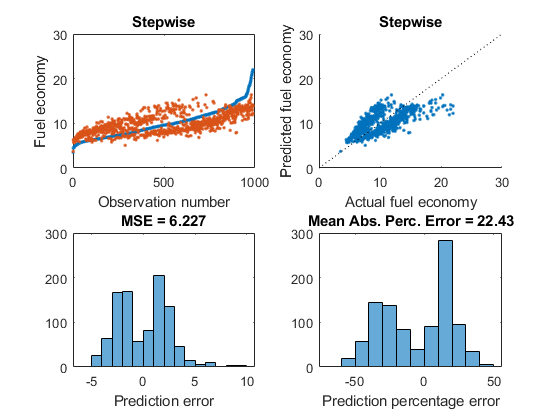

evaluatefit(carTest.FuelEcon,resppred,'Stepwise')

## Change criterion and limit to linear models

mdl = stepwiselm(carTrain,'Criterion','aic','Upper','linear');

1. Adding EngDisp, AIC = 7668.4759
2. Adding Weight, AIC = 7611.0894
3. Adding EVSpeedRatio, AIC = 7587.7821
4. Adding Comp, AIC = 7577.9294
5. Adding RatedHP, AIC = 7564.5345
6. Adding Valves_Cyl, AIC = 7560.7186


resppred = predict(mdl,carTest);

Elapsed time is 0.812853 seconds.


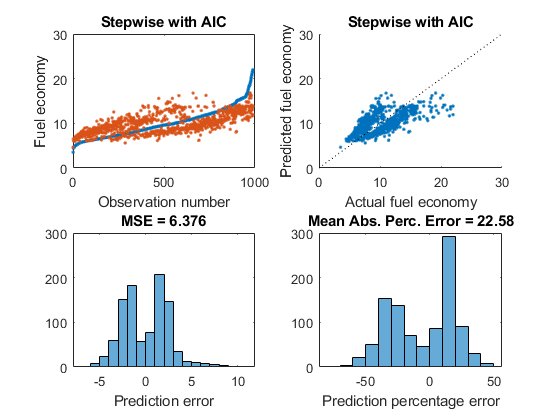

evaluatefit(carTest.FuelEcon,resppred,'Stepwise with AIC')